### Euler

clear;

N=3;
h=[1, 0.5, 0.25, 0.125];
y1(1)=0;
format = ['ro-'; 'yo-'; 'bo-'; 'go-']

format = 4×3 char array
    'ro-'
    'yo-'
    'bo-'
    'go-'


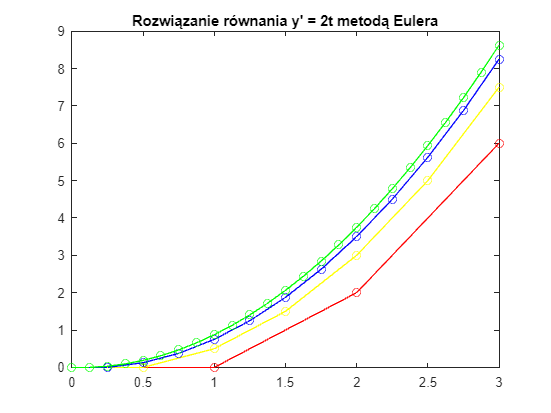


for j=1:length(h)
    t=0:h(j):N; 
    for i=1:N/h(j)
        dy=2*t(i);
        y1(i+1)=y1(i)+dy*h(j);
    end
    
    plot(t,y1,format(j,:))
    hold on;
end

title('Rozwiązanie równania y'' = 2t metodą Eulera')
hold off;

### ode45

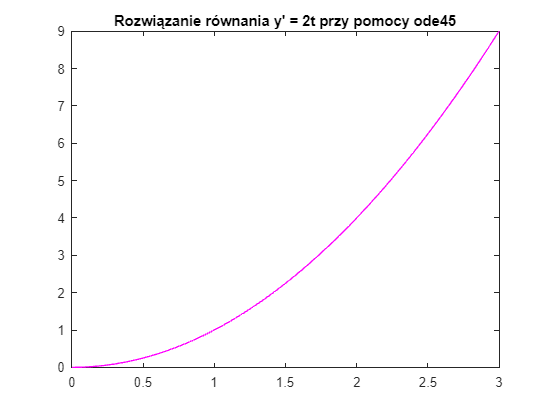

clear;

y0=0;
tspan=[0,3];
fun=@(T,Y) 2*T;
[T,Y]=ode45(fun,tspan,y0);
figure
plot(T,Y,'m-')
title('Rozwiązanie równania y'' = 2t przy pomocy ode45')
hold off;

### Wahadło

opts = odeset('stats','on');
tspan = [0 25];
y0 = [pi/4, 0];
[t,y] = ode45(@wahadlo, tspan, y0, opts);

96 successful steps
0 failed attempts
577 function evaluations


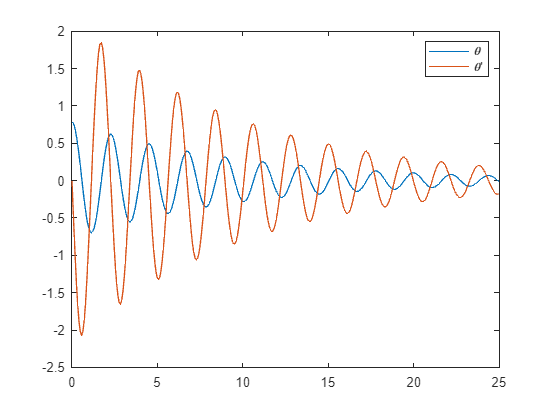

plot(t,y(:,1),t,y(:,2))
legend('\theta','\theta''')

### Urządzenie hamujące samolot - ode45

clear; 

global w3;
opts=odeset('stats','on');
tspan=[0 20];
y0 = [0 67 0 0 0 0];
[t,y] = ode45(@hamownik, tspan, y0, opts);

403 successful steps
27 failed attempts
2581 function evaluations


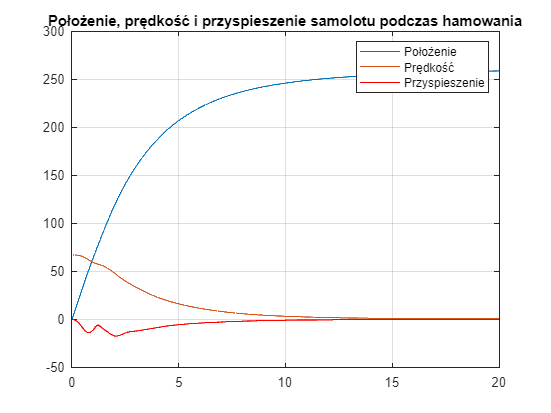

plot(t,y(:,1),t,y(:,2))
hold on;
options = odeset('OutputFcn',@hamownik_out,'Refine',1);
[T,Y] = ode45(@hamownik,tspan,y0,options);
plot(T,w3,'r')
grid ON;
title('Położenie, prędkość i przyspieszenie samolotu podczas hamowania')
legend('Położenie', 'Prędkość', 'Przyspieszenie');
hold off;